# EJERCICIOS ENTREGABLES PRÁCTICA 2-3

### Ejercicio 1 (2 puntos). Funciones de transferencia en MATLAB.

#### Se tiene la función de transferencia G ( s ) = $\frac{\alpha }{s^2 +s\;+\beta }$. Se pide encontrar, utilizando comandos de control de flujo (for, while, etc.) y tf/zpk, los valores de α y β que conduzcan a un sistema sobreamortiguado (con dos polos con parte real pura y diferente) aproximable a uno de primer orden con ganancia estática unitaria. Razone la respuesta.

alpha = 1; % Ganancia unitaria
for beta=-1:0.001:1
    if beta ~= 0
        G=tf([alpha], [1 1 beta]);
        chi = 1/(2*sqrt(beta)); % Calculamos chi
        if chi > 1 % Es sobreamortiguada
           chi
           s1 = -chi*sqrt(beta) + sqrt(beta)*sqrt(chi*chi - 1)
           s2 = -chi*sqrt(beta) - sqrt(beta)*sqrt(chi*chi - 1)
           G
           % Descartamos s2
           P = zpk([],[s1],alpha)
        end
    end
end

chi = 15.8114

s1 = -0.0010

s2 = -0.9990

G =
 
         1
  ---------------
  s^2 + s + 0.001
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  ------------
  (s+0.001001)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 11.1803

s1 = -0.0020

s2 = -0.9980

G =
 
         1
  ---------------
  s^2 + s + 0.002
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  ------------
  (s+0.002004)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 9.1287

s1 = -0.0030

s2 = -0.9970

G =
 
         1
  ---------------
  s^2 + s + 0.003
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  ------------
  (s+0.003009)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 7.9057

s1 = -0.0040

s2 = -0.9960

G =
 
         1
  ---------------
  s^2 + s + 0.004
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  ------------
  (s+0.004016)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 7.0711

s1 = -0.0050

s2 = -0.9950

G =
 
         1
  ---------------
  s^2 + s + 0.005
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  ------------
  (s+0.005025)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 6.4550

s1 = -0.0060

s2 = -0.9940

G =
 
         1
  ---------------
  s^2 + s + 0.006
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  ------------
  (s+0.006036)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 5.9761

s1 = -0.0070

s2 = -0.9930

G =
 
         1
  ---------------
  s^2 + s + 0.007
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.00705)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 5.5902

s1 = -0.0081

s2 = -0.9919

G =
 
         1
  ---------------
  s^2 + s + 0.008
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  ------------
  (s+0.008065)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 5.2705

s1 = -0.0091

s2 = -0.9909

G =
 
         1
  ---------------
  s^2 + s + 0.009
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  ------------
  (s+0.009082)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 5.0000

s1 = -0.0101

s2 = -0.9899

G =
 
        1
  --------------
  s^2 + s + 0.01
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.0101)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 4.7673

s1 = -0.0111

s2 = -0.9889

G =
 
         1
  ---------------
  s^2 + s + 0.011
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.01112)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 4.5644

s1 = -0.0121

s2 = -0.9879

G =
 
         1
  ---------------
  s^2 + s + 0.012
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.01215)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 4.3853

s1 = -0.0132

s2 = -0.9868

G =
 
         1
  ---------------
  s^2 + s + 0.013
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.01317)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 4.2258

s1 = -0.0142

s2 = -0.9858

G =
 
         1
  ---------------
  s^2 + s + 0.014
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.0142)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 4.0825

s1 = -0.0152

s2 = -0.9848

G =
 
         1
  ---------------
  s^2 + s + 0.015
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.01523)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 3.9528

s1 = -0.0163

s2 = -0.9837

G =
 
         1
  ---------------
  s^2 + s + 0.016
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.01626)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 3.8348

s1 = -0.0173

s2 = -0.9827

G =
 
         1
  ---------------
  s^2 + s + 0.017
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.0173)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 3.7268

s1 = -0.0183

s2 = -0.9817

G =
 
         1
  ---------------
  s^2 + s + 0.018
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.01834)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 3.6274

s1 = -0.0194

s2 = -0.9806

G =
 
         1
  ---------------
  s^2 + s + 0.019
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.01938)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 3.5355

s1 = -0.0204

s2 = -0.9796

G =
 
        1
  --------------
  s^2 + s + 0.02
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.02042)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 3.4503

s1 = -0.0215

s2 = -0.9785

G =
 
         1
  ---------------
  s^2 + s + 0.021
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.02146)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 3.3710

s1 = -0.0225

s2 = -0.9775

G =
 
         1
  ---------------
  s^2 + s + 0.022
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.02251)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 3.2969

s1 = -0.0236

s2 = -0.9764

G =
 
         1
  ---------------
  s^2 + s + 0.023
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.02355)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 3.2275

s1 = -0.0246

s2 = -0.9754

G =
 
         1
  ---------------
  s^2 + s + 0.024
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.02461)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 3.1623

s1 = -0.0257

s2 = -0.9743

G =
 
         1
  ---------------
  s^2 + s + 0.025
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.02566)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 3.1009

s1 = -0.0267

s2 = -0.9733

G =
 
         1
  ---------------
  s^2 + s + 0.026
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.02671)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 3.0429

s1 = -0.0278

s2 = -0.9722

G =
 
         1
  ---------------
  s^2 + s + 0.027
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.02777)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 2.9881

s1 = -0.0288

s2 = -0.9712

G =
 
         1
  ---------------
  s^2 + s + 0.028
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.02883)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 2.9361

s1 = -0.0299

s2 = -0.9701

G =
 
         1
  ---------------
  s^2 + s + 0.029
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.02989)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 2.8868

s1 = -0.0310

s2 = -0.9690

G =
 
        1
  --------------
  s^2 + s + 0.03
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.03096)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 2.8398

s1 = -0.0320

s2 = -0.9680

G =
 
         1
  ---------------
  s^2 + s + 0.031
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.03203)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 2.7951

s1 = -0.0331

s2 = -0.9669

G =
 
         1
  ---------------
  s^2 + s + 0.032
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.0331)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 2.7524

s1 = -0.0342

s2 = -0.9658

G =
 
         1
  ---------------
  s^2 + s + 0.033
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.03417)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 2.7116

s1 = -0.0352

s2 = -0.9648

G =
 
         1
  ---------------
  s^2 + s + 0.034
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.03524)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 2.6726

s1 = -0.0363

s2 = -0.9637

G =
 
         1
  ---------------
  s^2 + s + 0.035
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.03632)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 2.6352

s1 = -0.0374

s2 = -0.9626

G =
 
         1
  ---------------
  s^2 + s + 0.036
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.0374)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 2.5994

s1 = -0.0385

s2 = -0.9615

G =
 
         1
  ---------------
  s^2 + s + 0.037
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.03848)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 2.5649

s1 = -0.0396

s2 = -0.9604

G =
 
         1
  ---------------
  s^2 + s + 0.038
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.03957)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 2.5318

s1 = -0.0407

s2 = -0.9593

G =
 
         1
  ---------------
  s^2 + s + 0.039
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.04065)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 2.5000

s1 = -0.0417

s2 = -0.9583

G =
 
        1
  --------------
  s^2 + s + 0.04
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.04174)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 2.4693

s1 = -0.0428

s2 = -0.9572

G =
 
         1
  ---------------
  s^2 + s + 0.041
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.04283)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 2.4398

s1 = -0.0439

s2 = -0.9561

G =
 
         1
  ---------------
  s^2 + s + 0.042
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.04393)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 2.4112

s1 = -0.0450

s2 = -0.9550

G =
 
         1
  ---------------
  s^2 + s + 0.043
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.04503)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 2.3837

s1 = -0.0461

s2 = -0.9539

G =
 
         1
  ---------------
  s^2 + s + 0.044
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.04613)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 2.3570

s1 = -0.0472

s2 = -0.9528

G =
 
         1
  ---------------
  s^2 + s + 0.045
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.04723)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 2.3313

s1 = -0.0483

s2 = -0.9517

G =
 
         1
  ---------------
  s^2 + s + 0.046
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.04834)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 2.3063

s1 = -0.0494

s2 = -0.9506

G =
 
         1
  ---------------
  s^2 + s + 0.047
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.04944)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 2.2822

s1 = -0.0506

s2 = -0.9494

G =
 
         1
  ---------------
  s^2 + s + 0.048
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.05056)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 2.2588

s1 = -0.0517

s2 = -0.9483

G =
 
         1
  ---------------
  s^2 + s + 0.049
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.05167)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 2.2361

s1 = -0.0528

s2 = -0.9472

G =
 
        1
  --------------
  s^2 + s + 0.05
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.05279)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 2.2140

s1 = -0.0539

s2 = -0.9461

G =
 
         1
  ---------------
  s^2 + s + 0.051
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.05391)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 2.1926

s1 = -0.0550

s2 = -0.9450

G =
 
         1
  ---------------
  s^2 + s + 0.052
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.05503)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 2.1719

s1 = -0.0562

s2 = -0.9438

G =
 
         1
  ---------------
  s^2 + s + 0.053
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.05615)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 2.1517

s1 = -0.0573

s2 = -0.9427

G =
 
         1
  ---------------
  s^2 + s + 0.054
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.05728)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 2.1320

s1 = -0.0584

s2 = -0.9416

G =
 
         1
  ---------------
  s^2 + s + 0.055
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.05841)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 2.1129

s1 = -0.0595

s2 = -0.9405

G =
 
         1
  ---------------
  s^2 + s + 0.056
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.05955)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 2.0943

s1 = -0.0607

s2 = -0.9393

G =
 
         1
  ---------------
  s^2 + s + 0.057
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.06068)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 2.0761

s1 = -0.0618

s2 = -0.9382

G =
 
         1
  ---------------
  s^2 + s + 0.058
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.06182)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 2.0585

s1 = -0.0630

s2 = -0.9370

G =
 
         1
  ---------------
  s^2 + s + 0.059
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.06296)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 2.0412

s1 = -0.0641

s2 = -0.9359

G =
 
        1
  --------------
  s^2 + s + 0.06
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.06411)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 2.0244

s1 = -0.0653

s2 = -0.9347

G =
 
         1
  ---------------
  s^2 + s + 0.061
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.06526)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 2.0080

s1 = -0.0664

s2 = -0.9336

G =
 
         1
  ---------------
  s^2 + s + 0.062
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.06641)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.9920

s1 = -0.0676

s2 = -0.9324

G =
 
         1
  ---------------
  s^2 + s + 0.063
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.06757)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.9764

s1 = -0.0687

s2 = -0.9313

G =
 
         1
  ---------------
  s^2 + s + 0.064
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.06872)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.9612

s1 = -0.0699

s2 = -0.9301

G =
 
         1
  ---------------
  s^2 + s + 0.065
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.06988)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.9462

s1 = -0.0710

s2 = -0.9290

G =
 
         1
  ---------------
  s^2 + s + 0.066
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.07105)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.9317

s1 = -0.0722

s2 = -0.9278

G =
 
         1
  ---------------
  s^2 + s + 0.067
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.07222)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.9174

s1 = -0.0734

s2 = -0.9266

G =
 
         1
  ---------------
  s^2 + s + 0.068
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.07339)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.9035

s1 = -0.0746

s2 = -0.9254

G =
 
         1
  ---------------
  s^2 + s + 0.069
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.07456)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.8898

s1 = -0.0757

s2 = -0.9243

G =
 
        1
  --------------
  s^2 + s + 0.07
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.07574)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.8765

s1 = -0.0769

s2 = -0.9231

G =
 
         1
  ---------------
  s^2 + s + 0.071
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.07692)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.8634

s1 = -0.0781

s2 = -0.9219

G =
 
         1
  ---------------
  s^2 + s + 0.072
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.0781)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.8506

s1 = -0.0793

s2 = -0.9207

G =
 
         1
  ---------------
  s^2 + s + 0.073
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.07929)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.8380

s1 = -0.0805

s2 = -0.9195

G =
 
         1
  ---------------
  s^2 + s + 0.074
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.08048)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.8257

s1 = -0.0817

s2 = -0.9183

G =
 
         1
  ---------------
  s^2 + s + 0.075
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.08167)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.8137

s1 = -0.0829

s2 = -0.9171

G =
 
         1
  ---------------
  s^2 + s + 0.076
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.08287)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.8019

s1 = -0.0841

s2 = -0.9159

G =
 
         1
  ---------------
  s^2 + s + 0.077
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.08407)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.7903

s1 = -0.0853

s2 = -0.9147

G =
 
         1
  ---------------
  s^2 + s + 0.078
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.08527)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.7789

s1 = -0.0865

s2 = -0.9135

G =
 
         1
  ---------------
  s^2 + s + 0.079
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.08648)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.7678

s1 = -0.0877

s2 = -0.9123

G =
 
        1
  --------------
  s^2 + s + 0.08
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.08769)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.7568

s1 = -0.0889

s2 = -0.9111

G =
 
         1
  ---------------
  s^2 + s + 0.081
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.0889)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.7461

s1 = -0.0901

s2 = -0.9099

G =
 
         1
  ---------------
  s^2 + s + 0.082
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.09012)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.7355

s1 = -0.0913

s2 = -0.9087

G =
 
         1
  ---------------
  s^2 + s + 0.083
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.09134)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.7252

s1 = -0.0926

s2 = -0.9074

G =
 
         1
  ---------------
  s^2 + s + 0.084
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.09257)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.7150

s1 = -0.0938

s2 = -0.9062

G =
 
         1
  ---------------
  s^2 + s + 0.085
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.0938)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.7050

s1 = -0.0950

s2 = -0.9050

G =
 
         1
  ---------------
  s^2 + s + 0.086
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.09503)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.6952

s1 = -0.0963

s2 = -0.9037

G =
 
         1
  ---------------
  s^2 + s + 0.087
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.09627)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.6855

s1 = -0.0975

s2 = -0.9025

G =
 
         1
  ---------------
  s^2 + s + 0.088
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.09751)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.6760

s1 = -0.0988

s2 = -0.9012

G =
 
         1
  ---------------
  s^2 + s + 0.089
 
Continuous-time transfer function.
Model Properties


P =
 
       1
  -----------
  (s+0.09875)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.6667

s1 = -0.1000

s2 = -0.9000

G =
 
        1
  --------------
  s^2 + s + 0.09
 
Continuous-time transfer function.
Model Properties


P =
 
     1
  -------
  (s+0.1)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.6575

s1 = -0.1013

s2 = -0.8987

G =
 
         1
  ---------------
  s^2 + s + 0.091
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1013)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.6485

s1 = -0.1025

s2 = -0.8975

G =
 
         1
  ---------------
  s^2 + s + 0.092
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1025)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.6396

s1 = -0.1038

s2 = -0.8962

G =
 
         1
  ---------------
  s^2 + s + 0.093
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1038)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.6308

s1 = -0.1050

s2 = -0.8950

G =
 
         1
  ---------------
  s^2 + s + 0.094
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ---------
  (s+0.105)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.6222

s1 = -0.1063

s2 = -0.8937

G =
 
         1
  ---------------
  s^2 + s + 0.095
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1063)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.6137

s1 = -0.1076

s2 = -0.8924

G =
 
         1
  ---------------
  s^2 + s + 0.096
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1076)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.6054

s1 = -0.1088

s2 = -0.8912

G =
 
         1
  ---------------
  s^2 + s + 0.097
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1088)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.5972

s1 = -0.1101

s2 = -0.8899

G =
 
         1
  ---------------
  s^2 + s + 0.098
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1101)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.5891

s1 = -0.1114

s2 = -0.8886

G =
 
         1
  ---------------
  s^2 + s + 0.099
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1114)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.5811

s1 = -0.1127

s2 = -0.8873

G =
 
        1
  -------------
  s^2 + s + 0.1
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1127)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.5733

s1 = -0.1140

s2 = -0.8860

G =
 
         1
  ---------------
  s^2 + s + 0.101
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ---------
  (s+0.114)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.5656

s1 = -0.1153

s2 = -0.8847

G =
 
         1
  ---------------
  s^2 + s + 0.102
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1153)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.5579

s1 = -0.1166

s2 = -0.8834

G =
 
         1
  ---------------
  s^2 + s + 0.103
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1166)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.5504

s1 = -0.1179

s2 = -0.8821

G =
 
         1
  ---------------
  s^2 + s + 0.104
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1179)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.5430

s1 = -0.1192

s2 = -0.8808

G =
 
         1
  ---------------
  s^2 + s + 0.105
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1192)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.5357

s1 = -0.1205

s2 = -0.8795

G =
 
         1
  ---------------
  s^2 + s + 0.106
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1205)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.5285

s1 = -0.1218

s2 = -0.8782

G =
 
         1
  ---------------
  s^2 + s + 0.107
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1218)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.5215

s1 = -0.1232

s2 = -0.8768

G =
 
         1
  ---------------
  s^2 + s + 0.108
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1232)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.5145

s1 = -0.1245

s2 = -0.8755

G =
 
         1
  ---------------
  s^2 + s + 0.109
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1245)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.5076

s1 = -0.1258

s2 = -0.8742

G =
 
        1
  --------------
  s^2 + s + 0.11
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1258)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.5008

s1 = -0.1272

s2 = -0.8728

G =
 
         1
  ---------------
  s^2 + s + 0.111
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1272)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.4940

s1 = -0.1285

s2 = -0.8715

G =
 
         1
  ---------------
  s^2 + s + 0.112
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1285)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.4874

s1 = -0.1299

s2 = -0.8701

G =
 
         1
  ---------------
  s^2 + s + 0.113
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1299)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.4809

s1 = -0.1312

s2 = -0.8688

G =
 
         1
  ---------------
  s^2 + s + 0.114
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1312)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.4744

s1 = -0.1326

s2 = -0.8674

G =
 
         1
  ---------------
  s^2 + s + 0.115
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1326)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.4681

s1 = -0.1339

s2 = -0.8661

G =
 
         1
  ---------------
  s^2 + s + 0.116
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1339)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.4618

s1 = -0.1353

s2 = -0.8647

G =
 
         1
  ---------------
  s^2 + s + 0.117
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1353)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.4556

s1 = -0.1367

s2 = -0.8633

G =
 
         1
  ---------------
  s^2 + s + 0.118
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1367)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.4494

s1 = -0.1381

s2 = -0.8619

G =
 
         1
  ---------------
  s^2 + s + 0.119
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1381)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.4434

s1 = -0.1394

s2 = -0.8606

G =
 
        1
  --------------
  s^2 + s + 0.12
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1394)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.4374

s1 = -0.1408

s2 = -0.8592

G =
 
         1
  ---------------
  s^2 + s + 0.121
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1408)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.4315

s1 = -0.1422

s2 = -0.8578

G =
 
         1
  ---------------
  s^2 + s + 0.122
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1422)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.4257

s1 = -0.1436

s2 = -0.8564

G =
 
         1
  ---------------
  s^2 + s + 0.123
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1436)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.4199

s1 = -0.1450

s2 = -0.8550

G =
 
         1
  ---------------
  s^2 + s + 0.124
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ---------
  (s+0.145)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.4142

s1 = -0.1464

s2 = -0.8536

G =
 
         1
  ---------------
  s^2 + s + 0.125
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1464)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.4086

s1 = -0.1479

s2 = -0.8521

G =
 
         1
  ---------------
  s^2 + s + 0.126
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1479)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.4030

s1 = -0.1493

s2 = -0.8507

G =
 
         1
  ---------------
  s^2 + s + 0.127
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1493)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.3975

s1 = -0.1507

s2 = -0.8493

G =
 
         1
  ---------------
  s^2 + s + 0.128
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1507)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.3921

s1 = -0.1521

s2 = -0.8479

G =
 
         1
  ---------------
  s^2 + s + 0.129
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1521)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.3868

s1 = -0.1536

s2 = -0.8464

G =
 
        1
  --------------
  s^2 + s + 0.13
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1536)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.3814

s1 = -0.1550

s2 = -0.8450

G =
 
         1
  ---------------
  s^2 + s + 0.131
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ---------
  (s+0.155)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.3762

s1 = -0.1565

s2 = -0.8435

G =
 
         1
  ---------------
  s^2 + s + 0.132
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1565)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.3710

s1 = -0.1579

s2 = -0.8421

G =
 
         1
  ---------------
  s^2 + s + 0.133
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1579)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.3659

s1 = -0.1594

s2 = -0.8406

G =
 
         1
  ---------------
  s^2 + s + 0.134
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1594)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.3608

s1 = -0.1609

s2 = -0.8391

G =
 
         1
  ---------------
  s^2 + s + 0.135
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1609)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.3558

s1 = -0.1624

s2 = -0.8376

G =
 
         1
  ---------------
  s^2 + s + 0.136
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1624)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.3509

s1 = -0.1638

s2 = -0.8362

G =
 
         1
  ---------------
  s^2 + s + 0.137
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1638)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.3460

s1 = -0.1653

s2 = -0.8347

G =
 
         1
  ---------------
  s^2 + s + 0.138
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1653)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.3411

s1 = -0.1668

s2 = -0.8332

G =
 
         1
  ---------------
  s^2 + s + 0.139
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1668)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.3363

s1 = -0.1683

s2 = -0.8317

G =
 
        1
  --------------
  s^2 + s + 0.14
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1683)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.3316

s1 = -0.1698

s2 = -0.8302

G =
 
         1
  ---------------
  s^2 + s + 0.141
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1698)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.3269

s1 = -0.1714

s2 = -0.8286

G =
 
         1
  ---------------
  s^2 + s + 0.142
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1714)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.3222

s1 = -0.1729

s2 = -0.8271

G =
 
         1
  ---------------
  s^2 + s + 0.143
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1729)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.3176

s1 = -0.1744

s2 = -0.8256

G =
 
         1
  ---------------
  s^2 + s + 0.144
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1744)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.3131

s1 = -0.1760

s2 = -0.8240

G =
 
         1
  ---------------
  s^2 + s + 0.145
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ---------
  (s+0.176)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.3086

s1 = -0.1775

s2 = -0.8225

G =
 
         1
  ---------------
  s^2 + s + 0.146
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1775)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.3041

s1 = -0.1791

s2 = -0.8209

G =
 
         1
  ---------------
  s^2 + s + 0.147
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1791)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.2997

s1 = -0.1806

s2 = -0.8194

G =
 
         1
  ---------------
  s^2 + s + 0.148
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1806)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.2953

s1 = -0.1822

s2 = -0.8178

G =
 
         1
  ---------------
  s^2 + s + 0.149
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1822)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.2910

s1 = -0.1838

s2 = -0.8162

G =
 
        1
  --------------
  s^2 + s + 0.15
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1838)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.2867

s1 = -0.1854

s2 = -0.8146

G =
 
         1
  ---------------
  s^2 + s + 0.151
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1854)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.2825

s1 = -0.1870

s2 = -0.8130

G =
 
         1
  ---------------
  s^2 + s + 0.152
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ---------
  (s+0.187)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.2783

s1 = -0.1886

s2 = -0.8114

G =
 
         1
  ---------------
  s^2 + s + 0.153
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1886)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.2741

s1 = -0.1902

s2 = -0.8098

G =
 
         1
  ---------------
  s^2 + s + 0.154
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1902)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.2700

s1 = -0.1918

s2 = -0.8082

G =
 
         1
  ---------------
  s^2 + s + 0.155
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1918)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.2659

s1 = -0.1934

s2 = -0.8066

G =
 
         1
  ---------------
  s^2 + s + 0.156
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1934)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.2619

s1 = -0.1950

s2 = -0.8050

G =
 
         1
  ---------------
  s^2 + s + 0.157
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ---------
  (s+0.195)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.2579

s1 = -0.1967

s2 = -0.8033

G =
 
         1
  ---------------
  s^2 + s + 0.158
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1967)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.2539

s1 = -0.1983

s2 = -0.8017

G =
 
         1
  ---------------
  s^2 + s + 0.159
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.1983)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.2500

s1 = -0.2000

s2 = -0.8000

G =
 
        1
  --------------
  s^2 + s + 0.16
 
Continuous-time transfer function.
Model Properties


P =
 
     1
  -------
  (s+0.2)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.2461

s1 = -0.2017

s2 = -0.7983

G =
 
         1
  ---------------
  s^2 + s + 0.161
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.2017)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.2423

s1 = -0.2034

s2 = -0.7966

G =
 
         1
  ---------------
  s^2 + s + 0.162
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.2034)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.2384

s1 = -0.2050

s2 = -0.7950

G =
 
         1
  ---------------
  s^2 + s + 0.163
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ---------
  (s+0.205)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.2347

s1 = -0.2067

s2 = -0.7933

G =
 
         1
  ---------------
  s^2 + s + 0.164
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.2067)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.2309

s1 = -0.2085

s2 = -0.7915

G =
 
         1
  ---------------
  s^2 + s + 0.165
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.2085)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.2272

s1 = -0.2102

s2 = -0.7898

G =
 
         1
  ---------------
  s^2 + s + 0.166
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.2102)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.2235

s1 = -0.2119

s2 = -0.7881

G =
 
         1
  ---------------
  s^2 + s + 0.167
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.2119)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.2199

s1 = -0.2136

s2 = -0.7864

G =
 
         1
  ---------------
  s^2 + s + 0.168
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.2136)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.2163

s1 = -0.2154

s2 = -0.7846

G =
 
         1
  ---------------
  s^2 + s + 0.169
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.2154)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.2127

s1 = -0.2172

s2 = -0.7828

G =
 
        1
  --------------
  s^2 + s + 0.17
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.2172)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.2091

s1 = -0.2189

s2 = -0.7811

G =
 
         1
  ---------------
  s^2 + s + 0.171
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.2189)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.2056

s1 = -0.2207

s2 = -0.7793

G =
 
         1
  ---------------
  s^2 + s + 0.172
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.2207)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.2021

s1 = -0.2225

s2 = -0.7775

G =
 
         1
  ---------------
  s^2 + s + 0.173
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.2225)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.1987

s1 = -0.2243

s2 = -0.7757

G =
 
         1
  ---------------
  s^2 + s + 0.174
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.2243)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.1952

s1 = -0.2261

s2 = -0.7739

G =
 
         1
  ---------------
  s^2 + s + 0.175
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.2261)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.1918

s1 = -0.2280

s2 = -0.7720

G =
 
         1
  ---------------
  s^2 + s + 0.176
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ---------
  (s+0.228)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.1885

s1 = -0.2298

s2 = -0.7702

G =
 
         1
  ---------------
  s^2 + s + 0.177
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.2298)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.1851

s1 = -0.2317

s2 = -0.7683

G =
 
         1
  ---------------
  s^2 + s + 0.178
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.2317)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.1818

s1 = -0.2335

s2 = -0.7665

G =
 
         1
  ---------------
  s^2 + s + 0.179
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.2335)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.1785

s1 = -0.2354

s2 = -0.7646

G =
 
        1
  --------------
  s^2 + s + 0.18
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.2354)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.1753

s1 = -0.2373

s2 = -0.7627

G =
 
         1
  ---------------
  s^2 + s + 0.181
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.2373)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.1720

s1 = -0.2392

s2 = -0.7608

G =
 
         1
  ---------------
  s^2 + s + 0.182
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.2392)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.1688

s1 = -0.2412

s2 = -0.7588

G =
 
         1
  ---------------
  s^2 + s + 0.183
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.2412)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.1656

s1 = -0.2431

s2 = -0.7569

G =
 
         1
  ---------------
  s^2 + s + 0.184
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.2431)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.1625

s1 = -0.2450

s2 = -0.7550

G =
 
         1
  ---------------
  s^2 + s + 0.185
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ---------
  (s+0.245)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.1593

s1 = -0.2470

s2 = -0.7530

G =
 
         1
  ---------------
  s^2 + s + 0.186
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ---------
  (s+0.247)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.1562

s1 = -0.2490

s2 = -0.7510

G =
 
         1
  ---------------
  s^2 + s + 0.187
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ---------
  (s+0.249)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.1532

s1 = -0.2510

s2 = -0.7490

G =
 
         1
  ---------------
  s^2 + s + 0.188
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ---------
  (s+0.251)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.1501

s1 = -0.2530

s2 = -0.7470

G =
 
         1
  ---------------
  s^2 + s + 0.189
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ---------
  (s+0.253)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.1471

s1 = -0.2551

s2 = -0.7449

G =
 
        1
  --------------
  s^2 + s + 0.19
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.2551)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.1441

s1 = -0.2571

s2 = -0.7429

G =
 
         1
  ---------------
  s^2 + s + 0.191
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.2571)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.1411

s1 = -0.2592

s2 = -0.7408

G =
 
         1
  ---------------
  s^2 + s + 0.192
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.2592)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.1381

s1 = -0.2613

s2 = -0.7387

G =
 
         1
  ---------------
  s^2 + s + 0.193
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.2613)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.1352

s1 = -0.2634

s2 = -0.7366

G =
 
         1
  ---------------
  s^2 + s + 0.194
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.2634)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.1323

s1 = -0.2655

s2 = -0.7345

G =
 
         1
  ---------------
  s^2 + s + 0.195
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.2655)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.1294

s1 = -0.2676

s2 = -0.7324

G =
 
         1
  ---------------
  s^2 + s + 0.196
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.2676)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.1265

s1 = -0.2698

s2 = -0.7302

G =
 
         1
  ---------------
  s^2 + s + 0.197
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.2698)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.1237

s1 = -0.2720

s2 = -0.7280

G =
 
         1
  ---------------
  s^2 + s + 0.198
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ---------
  (s+0.272)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.1208

s1 = -0.2742

s2 = -0.7258

G =
 
         1
  ---------------
  s^2 + s + 0.199
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.2742)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.1180

s1 = -0.2764

s2 = -0.7236

G =
 
        1
  -------------
  s^2 + s + 0.2
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.2764)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.1152

s1 = -0.2786

s2 = -0.7214

G =
 
         1
  ---------------
  s^2 + s + 0.201
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.2786)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.1125

s1 = -0.2809

s2 = -0.7191

G =
 
         1
  ---------------
  s^2 + s + 0.202
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.2809)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.1097

s1 = -0.2832

s2 = -0.7168

G =
 
         1
  ---------------
  s^2 + s + 0.203
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.2832)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.1070

s1 = -0.2855

s2 = -0.7145

G =
 
         1
  ---------------
  s^2 + s + 0.204
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.2855)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.1043

s1 = -0.2879

s2 = -0.7121

G =
 
         1
  ---------------
  s^2 + s + 0.205
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.2879)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.1016

s1 = -0.2902

s2 = -0.7098

G =
 
         1
  ---------------
  s^2 + s + 0.206
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.2902)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0990

s1 = -0.2926

s2 = -0.7074

G =
 
         1
  ---------------
  s^2 + s + 0.207
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.2926)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0963

s1 = -0.2951

s2 = -0.7049

G =
 
         1
  ---------------
  s^2 + s + 0.208
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.2951)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0937

s1 = -0.2975

s2 = -0.7025

G =
 
         1
  ---------------
  s^2 + s + 0.209
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.2975)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0911

s1 = -0.3000

s2 = -0.7000

G =
 
        1
  --------------
  s^2 + s + 0.21
 
Continuous-time transfer function.
Model Properties


P =
 
     1
  -------
  (s+0.3)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0885

s1 = -0.3025

s2 = -0.6975

G =
 
         1
  ---------------
  s^2 + s + 0.211
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.3025)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0859

s1 = -0.3051

s2 = -0.6949

G =
 
         1
  ---------------
  s^2 + s + 0.212
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.3051)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0834

s1 = -0.3076

s2 = -0.6924

G =
 
         1
  ---------------
  s^2 + s + 0.213
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.3076)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0808

s1 = -0.3103

s2 = -0.6897

G =
 
         1
  ---------------
  s^2 + s + 0.214
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.3103)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0783

s1 = -0.3129

s2 = -0.6871

G =
 
         1
  ---------------
  s^2 + s + 0.215
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.3129)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0758

s1 = -0.3156

s2 = -0.6844

G =
 
         1
  ---------------
  s^2 + s + 0.216
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.3156)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0733

s1 = -0.3183

s2 = -0.6817

G =
 
         1
  ---------------
  s^2 + s + 0.217
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.3183)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0709

s1 = -0.3211

s2 = -0.6789

G =
 
         1
  ---------------
  s^2 + s + 0.218
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.3211)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0684

s1 = -0.3239

s2 = -0.6761

G =
 
         1
  ---------------
  s^2 + s + 0.219
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.3239)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0660

s1 = -0.3268

s2 = -0.6732

G =
 
        1
  --------------
  s^2 + s + 0.22
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.3268)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0636

s1 = -0.3297

s2 = -0.6703

G =
 
         1
  ---------------
  s^2 + s + 0.221
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.3297)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0612

s1 = -0.3327

s2 = -0.6673

G =
 
         1
  ---------------
  s^2 + s + 0.222
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.3327)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0588

s1 = -0.3357

s2 = -0.6643

G =
 
         1
  ---------------
  s^2 + s + 0.223
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.3357)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0564

s1 = -0.3388

s2 = -0.6612

G =
 
         1
  ---------------
  s^2 + s + 0.224
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.3388)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0541

s1 = -0.3419

s2 = -0.6581

G =
 
         1
  ---------------
  s^2 + s + 0.225
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.3419)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0518

s1 = -0.3451

s2 = -0.6549

G =
 
         1
  ---------------
  s^2 + s + 0.226
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.3451)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0494

s1 = -0.3483

s2 = -0.6517

G =
 
         1
  ---------------
  s^2 + s + 0.227
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.3483)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0471

s1 = -0.3517

s2 = -0.6483

G =
 
         1
  ---------------
  s^2 + s + 0.228
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.3517)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0448

s1 = -0.3551

s2 = -0.6449

G =
 
         1
  ---------------
  s^2 + s + 0.229
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.3551)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0426

s1 = -0.3586

s2 = -0.6414

G =
 
        1
  --------------
  s^2 + s + 0.23
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.3586)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0403

s1 = -0.3622

s2 = -0.6378

G =
 
         1
  ---------------
  s^2 + s + 0.231
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.3622)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0381

s1 = -0.3658

s2 = -0.6342

G =
 
         1
  ---------------
  s^2 + s + 0.232
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.3658)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0358

s1 = -0.3696

s2 = -0.6304

G =
 
         1
  ---------------
  s^2 + s + 0.233
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.3696)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0336

s1 = -0.3735

s2 = -0.6265

G =
 
         1
  ---------------
  s^2 + s + 0.234
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.3735)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0314

s1 = -0.3775

s2 = -0.6225

G =
 
         1
  ---------------
  s^2 + s + 0.235
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.3775)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0292

s1 = -0.3817

s2 = -0.6183

G =
 
         1
  ---------------
  s^2 + s + 0.236
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.3817)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0271

s1 = -0.3860

s2 = -0.6140

G =
 
         1
  ---------------
  s^2 + s + 0.237
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ---------
  (s+0.386)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0249

s1 = -0.3905

s2 = -0.6095

G =
 
         1
  ---------------
  s^2 + s + 0.238
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.3905)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0228

s1 = -0.3951

s2 = -0.6049

G =
 
         1
  ---------------
  s^2 + s + 0.239
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.3951)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0206

s1 = -0.4000

s2 = -0.6000

G =
 
        1
  --------------
  s^2 + s + 0.24
 
Continuous-time transfer function.
Model Properties


P =
 
     1
  -------
  (s+0.4)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0185

s1 = -0.4051

s2 = -0.5949

G =
 
         1
  ---------------
  s^2 + s + 0.241
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.4051)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0164

s1 = -0.4106

s2 = -0.5894

G =
 
         1
  ---------------
  s^2 + s + 0.242
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.4106)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0143

s1 = -0.4163

s2 = -0.5837

G =
 
         1
  ---------------
  s^2 + s + 0.243
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.4163)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0122

s1 = -0.4225

s2 = -0.5775

G =
 
         1
  ---------------
  s^2 + s + 0.244
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.4225)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0102

s1 = -0.4293

s2 = -0.5707

G =
 
         1
  ---------------
  s^2 + s + 0.245
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.4293)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0081

s1 = -0.4368

s2 = -0.5632

G =
 
         1
  ---------------
  s^2 + s + 0.246
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.4368)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0061

s1 = -0.4452

s2 = -0.5548

G =
 
         1
  ---------------
  s^2 + s + 0.247
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.4452)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0040

s1 = -0.4553

s2 = -0.5447

G =
 
         1
  ---------------
  s^2 + s + 0.248
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.4553)
 
Continuous-time zero/pole/gain model.
Model Properties


chi = 1.0020

s1 = -0.4684

s2 = -0.5316

G =
 
         1
  ---------------
  s^2 + s + 0.249
 
Continuous-time transfer function.
Model Properties


P =
 
      1
  ----------
  (s+0.4684)
 
Continuous-time zero/pole/gain model.
Model Properties


**Antes de ejecutar el código, procederemos a explicarlo:**

- Alpha lo igualamos a 1, ya que para coseguir un sistema de primer orden con ganancia unitaria, necesitamos reducir el orden del sistema usando aproximacion por polos dominantes y la ganancia del sistema original sera la misma del aproximado, luego como alpha es igual a k·beta si se puede igualar a 1.

- El for lo vamos a usar para que nos pruebe distintos valores de beta, en el rango desde -1 hasta 1, y con el if nos aseguramos no crear una funcion de transferencia nula.

- Definimos usando tf la funcion de transferencia del sistema.

- A continuacion usamos if para comprobar si chi es mayor que 1, es decir que el sistema es sobreamortiguado, y si lo es mostramos el valor de chi y de los polos resultantes.

- Como cuando chi >> 1 podemos descartar el polo mas rapido s2, el sistema queda dominado por s1, es decir un sistema de primer orden con ganancia alpha que es unitaria.

- Y por ultimo, la línea de zpk nos crea el sistema de primer orden deseado.

**Ahora, si lo ejecutamos:**

Observamos los resultados obtenidos y podemos apreciar que los valores deseados para alpha es 1 y que cuanto mas cerac de 0 este beta mas alto sera el valor de chi, y por lo tanto mayor sera la disparidad entre los 2 polos. Luego nos vamos a quedar con beta = 0.001 ya que da el valor de chi mas alto. El sistema resultante queda: 

alpha = 1;
beta = 0.001;

G=tf([alpha], [1 1 beta])

G =
 
         1
  ---------------
  s^2 + s + 0.001
 
Continuous-time transfer function.
Model Properties



chi = 1/(2*sqrt(beta))

chi = 15.8114

s1 = -chi*sqrt(beta) + sqrt(beta)*sqrt(chi*chi - 1)

s1 = -0.0010

s2 = -chi*sqrt(beta) - sqrt(beta)*sqrt(chi*chi - 1)

s2 = -0.9990


%Descartamos s2
P = zpk([],[s1],alpha)

P =
 
       1
  ------------
  (s+0.001001)
 
Continuous-time zero/pole/gain model.
Model Properties


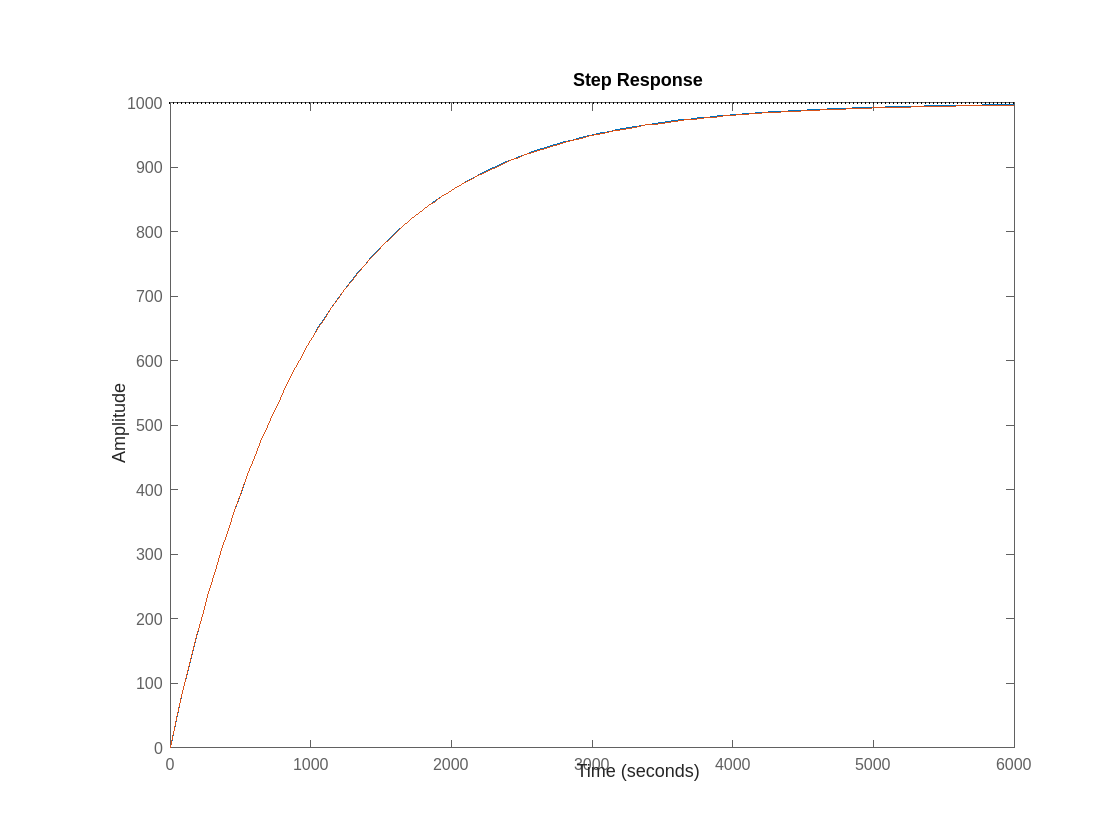


% Lo mostramos frente a una entrada escalon
step(G,P)

% Son muy similares